% perturbative NE

% create the set of linear equations
J = 1;
Gm = 1.2;
h = 0.1; % start with IM with transverse field only
N = 6;
bc = 'PBC';
[H,Hloc] = hIM(J,Gm,h,N,bc,1); % create global and local Hamiltonians

v = spec(:,1);
f0 = @(phi) fPT(v,phi,N,Hloc);
df0 = @(phi,h) fdPT(v,phi,N,Hloc,h);

ftol = 1e-10;
tic
[phi,fval] = NEsolver(phi0,f0,df0,ftol)

phi =    -0.2245
   -0.0607
    0.0243
   -0.0018
   -0.0898
    0.2018
    0.0967
   -0.0009
    0.0240
    0.1795


fval = 3.4366e-11

toc

Elapsed time is 69.517133 seconds.


% explicit iterations to check convergence
% make iterations
% convergence condition:
iter = 1;

% converge if the function converges to the 
ftol = 1e-14;

% terminate if beyond maximal allowed iterations
max_iter = 50;

% initial conditions
% phi
phi = 1-2*rand(2^N,1);
phi = phi/norm(phi);
% fval
fval = f0(phi);
% aopt
aopt = 0.033;

% record data
fvals = [];
aopts = [];
tic
while and(fval>ftol,iter<max_iter)
    
    % for computations
    h = sqrt(2.2e-16); % the finite difference used for finding derivatives
    tol = min(1e-4,1e-3*aopt);
    options = optimset('TolX',tol);
    
    
    if iter == 1
        disp(['iter = 1, fval = ',num2str(fval),', aopt = ',num2str(aopt)])
    end
    % choose the descent direction to be the gradient
    nn = -df0(phi,h)/norm(df0(phi,h));
    
    % choose the amount of descent, i.e. stepsize e
    % by exact line search
    % Construct a function handle
    ftemp = @(ak) f0(phi+ak*nn);
    
    % use builtin opt package to minimize ftemp
    [aopt,fval] = fminbnd(ftemp,0,2*aopt,options);
    
    phi = phi + aopt*nn;
    phi = phi/norm(phi); % normalize the resultant state
    iter = iter + 1;
    
    disp(['iter = ',num2str(iter),', fval = ',num2str(fval),', aopt = ',num2str(aopt)]);

    fvals = [fvals,fval];
    aopts = [aopts,aopt];
end

iter = 1, fval = 1.8265, aopt = 0.033


iter = 2, fval = 0.44066, aopt = 0.065982
iter = 3, fval = 0.0067769, aopt = 0.061421
iter = 4, fval = 0.0013374, aopt = 0.0068136
iter = 5, fval = 0.00028955, aopt = 0.0023302
iter = 6, fval = 7.0034e-05, aopt = 0.0013175
iter = 7, fval = 1.6992e-05, aopt = 0.00052168
iter = 8, fval = 4.1399e-06, aopt = 0.00031838
iter = 9, fval = 1.0089e-06, aopt = 0.00012674
iter = 10, fval = 2.4594e-07, aopt = 7.7574e-05
iter = 11, fval = 5.9957e-08, aopt = 3.0891e-05
iter = 12, fval = 1.4618e-08, aopt = 1.8911e-05
iter = 13, fval = 3.5642e-09, aopt = 7.5311e-06
iter = 14, fval = 8.6903e-10, aopt = 4.6107e-06
iter = 15, fval = 2.1189e-10, aopt = 1.8362e-06
iter = 16, fval = 5.1666e-11, aopt = 1.1242e-06
iter = 17, fval = 1.2598e-11, aopt = 4.4773e-07
iter = 18, fval = 3.0718e-12, aopt = 2.7412e-07
iter = 19, fval = 7.4901e-13, aopt = 1.0917e-07
iter = 20, fval = 1.8263e-13, aopt = 6.6838e-08
iter = 21, fval = 4.4532e-14, aopt = 2.6619e-08
iter = 22, fval = 1.0859e-14, aopt = 1.6298e-08
iter = 23, f

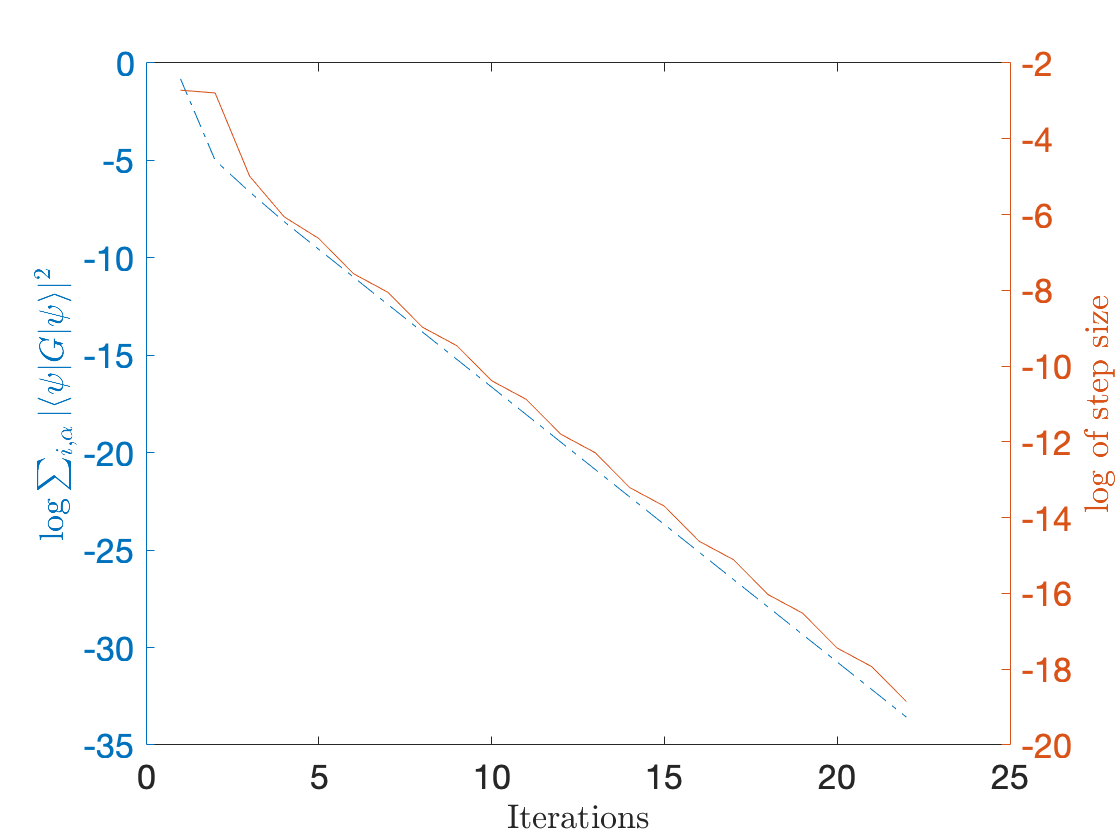

figure();
yyaxis left
% check that the convergence is reached
% plot(1:itermax,eset,'*-','LineWidth',1.5)
% ylabel('Convergence measure $\epsilon$')

plot(1:iter-1,log(fvals),'-.')
ylabel('$\log \sum_{i,\alpha} | \langle \psi | G | \psi \rangle |^2 $')
yyaxis right
% % make sure the convergent state satisfy the kernel condition
% plot(1:itermax,lset,'o-.','LineWidth',0.5)
% ylabel('Kernel measure $l = \sum_{G} |\langle \psi |G| \psi \rangle |$')
% format short

plot(1:iter-1,log(aopts))
ylabel('log of step size')
xlabel('Iterations')

% construct the new state

fvals =     0.4407    0.0068    0.0013    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


function y = fPT(psi,phi,N,Hloc)
    y = 0;
    for j = 1:N
        for a = 1:3
            G = fG(j,a,Hloc);
            dG = fdG(N,j,a);
            y = y + ((psi'*dG*psi)*(phi'*G*phi)-4*real(psi'*G*phi)*real(psi'*dG*phi))^2/(phi'*phi)^2;
        end
    end
end

function dydx = fdPT(psi,phi,N,Hloc,h)
    dydx = zeros(length(phi),1);
    for i = 1:length(phi)
        dx = zeros(length(phi),1);
        dx(i) = h;
        dydx(i) = (fPT(psi,phi+dx,N,Hloc)-fPT(psi,phi-dx,N,Hloc))/(2*h);
    end
end